# Lab 1 Notebook

## A. The Normal Distribution

A normal distribution a set of data points which is centered around the mean value. It is symmetric, with mean (mu) = median = mode, and is often called a "Gaussian distribution" or a "bell curve" due to its shape, as seen to the right.

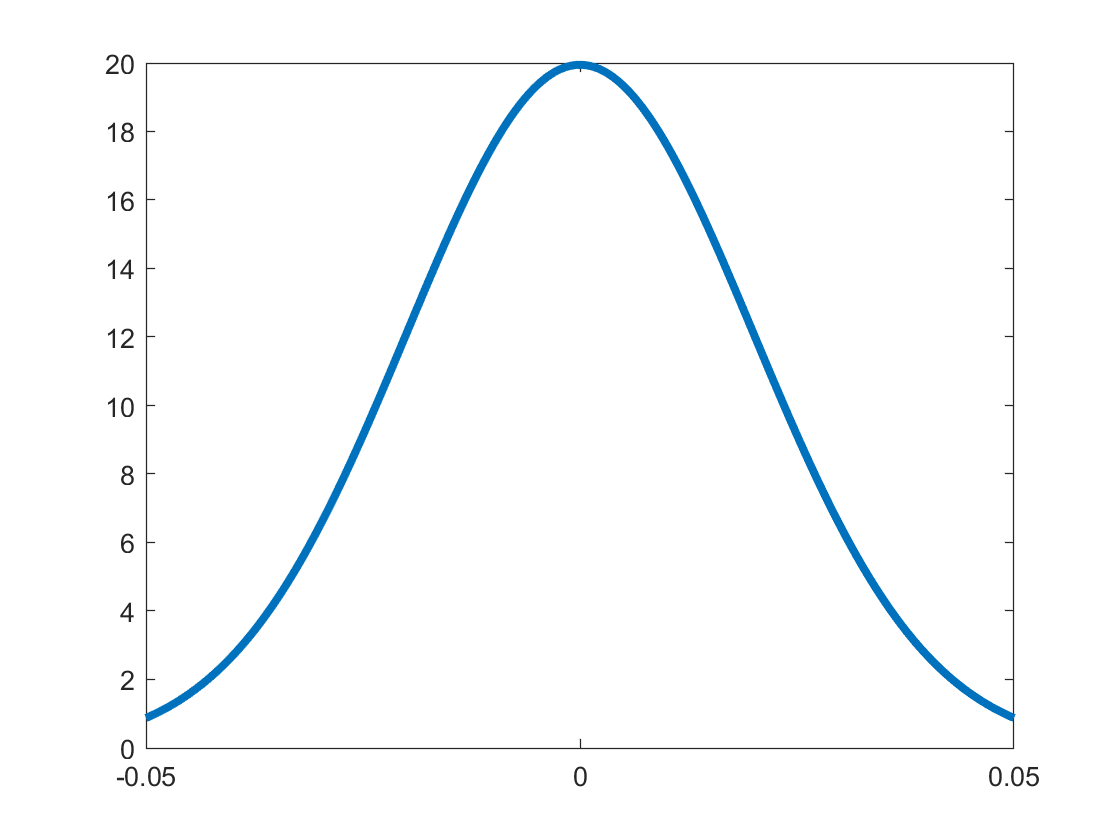

x = linspace(-0.05,0.05,1000);
bellcurve = makedist("Normal","mu",0.,"sigma",0.02);
plot(x,pdf(bellcurve,x),"LineWidth",3)

One numerical value associated with a normal distribution is the standard deviation, represented by a sigma. Standard deviation is a measure of the spread of the data, for instance a smaller standard deviation results in a thinner, higher peak whereas a larger standard deviation indicates a wider, more spread out set of data points. 

Generally, 68% of values are within one standard deviation of the mean, 95% of values are within two standard deviations, and 99.7% of values are within three standard deviations. 

### The Standard Normal Distribution

In a standard normal distribution, which is a particular subset of normal distributions, the mean is 0 and the standard deviation is 1. 

### Mathematical Representation

Typical probability density function: 

f(x) = 1/(sigma*sqrt(2*pi))*exp(-0.5*((x-mu)/sigma)^2)

Standard normal probablility density function:

p(x) = 1/sqrt(2*pi)*exp(-0.5*x^2)

Note that the factor 1/(sigma*sqrt(2*pi)) lets the integral from negative infinity to positive infinity be 1, effectively normalizing the data and allowing the function to give a probability. Taking the integral of f on the interval [a,b] gives the probability of a data point being in that section of the distribution. 

## B. Integrating the Standard Normal Distribution

Below are examples of finding probabilities by integrating normal distributions of various sigmas.

- Standard normal: mu = 0, sigma = 1

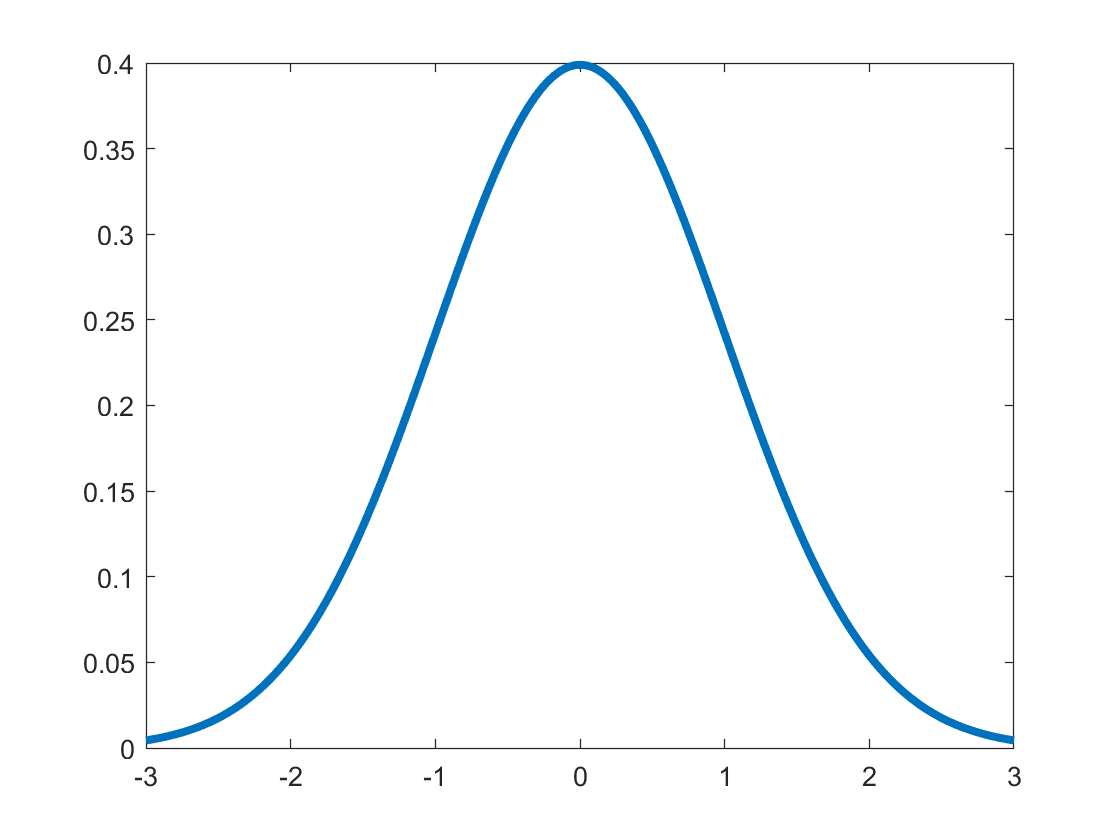

x2 = linspace(-3,3,1000);
bellcurve2 = makedist("Normal","mu",0.,"sigma",1);
plot(x2,pdf(bellcurve2,x2),"LineWidth",3)


p_a = normcdf(-1.5)

p_a = 0.0668


p_b = normcdf(1.5)

p_b = 0.9332


c = [-1,1];
prob_c = normcdf(c);
p_c = prob_c(2)-prob_c(1)

p_c = 0.6827

           2. mu = 0, sigma = 0.5

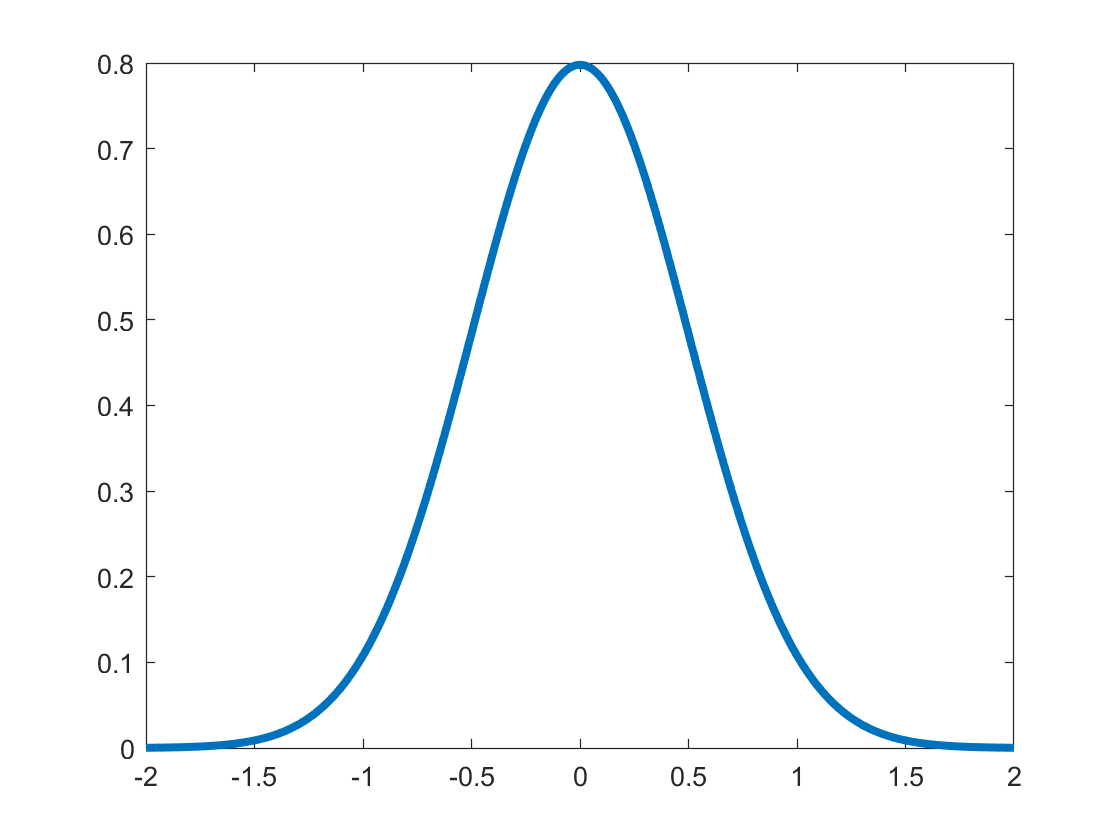

x3 = linspace(-2,2,1000);
bellcurve3 = makedist("Normal","mu",0.,"sigma",0.5);
plot(x3,pdf(bellcurve3,x3),"LineWidth",3)


p_d = normcdf(-1.5,0,0.5)

p_d = 0.0013


p_e = normcdf(1.5,0,0.5)

p_e = 0.9987


p_f = normcdf(1,0,0.5) - normcdf(-1,0,0.5)

p_f = 0.9545

            3. mu = 0, sigma = 2

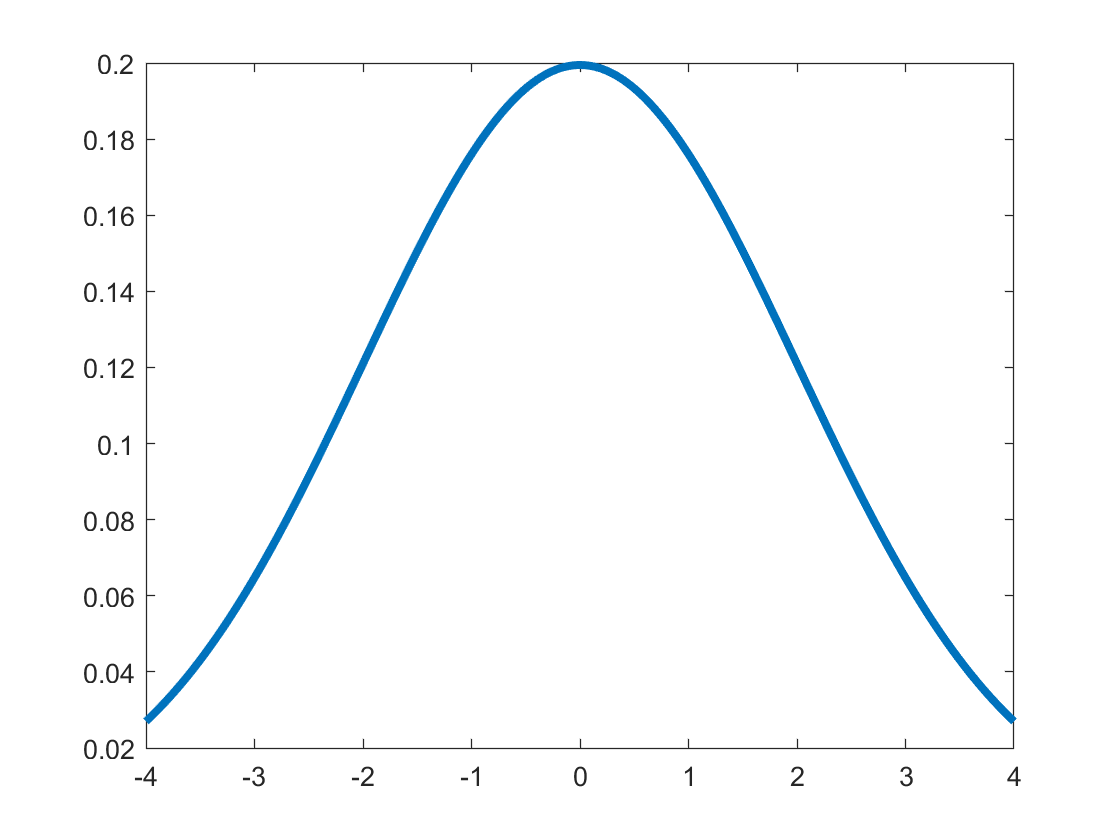

x4 = linspace(-4,4,1000);
bellcurve4 = makedist("Normal","mu",0.,"sigma",2);
plot(x4,pdf(bellcurve4,x4),"LineWidth",3)


p_g = normcdf(-1.5,0,2)

p_g = 0.2266


p_h = normcdf(1.5,0,2)

p_h = 0.7734


p_i = normcdf(1,0,2) - normcdf(-1,0,2)

p_i = 0.3829

The various graphs show how sigma affects the spread of the graph, and the probabilities listed below give values for the intervals

- (-infinity, -1.5)

- (-infinity, 1.5)

- (-1,1)

for all three sigmas. 

<z table values>

C. <Title for part C> <'Sigmas'>

<brief description of what 'sigma' entails in this context>

Examples of <norminv> or <erfcinv> trying several probability values with known outcomes

D. <Negative 'sigma'> 

<what does it entail?>